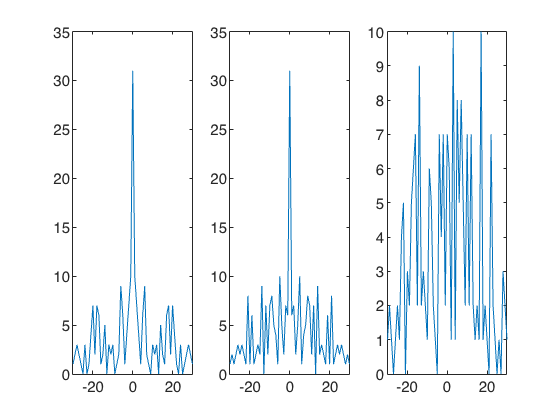

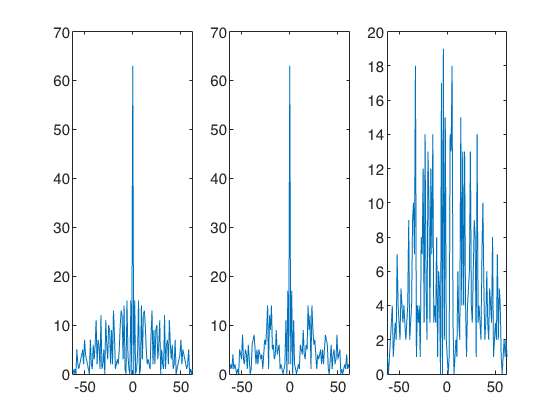

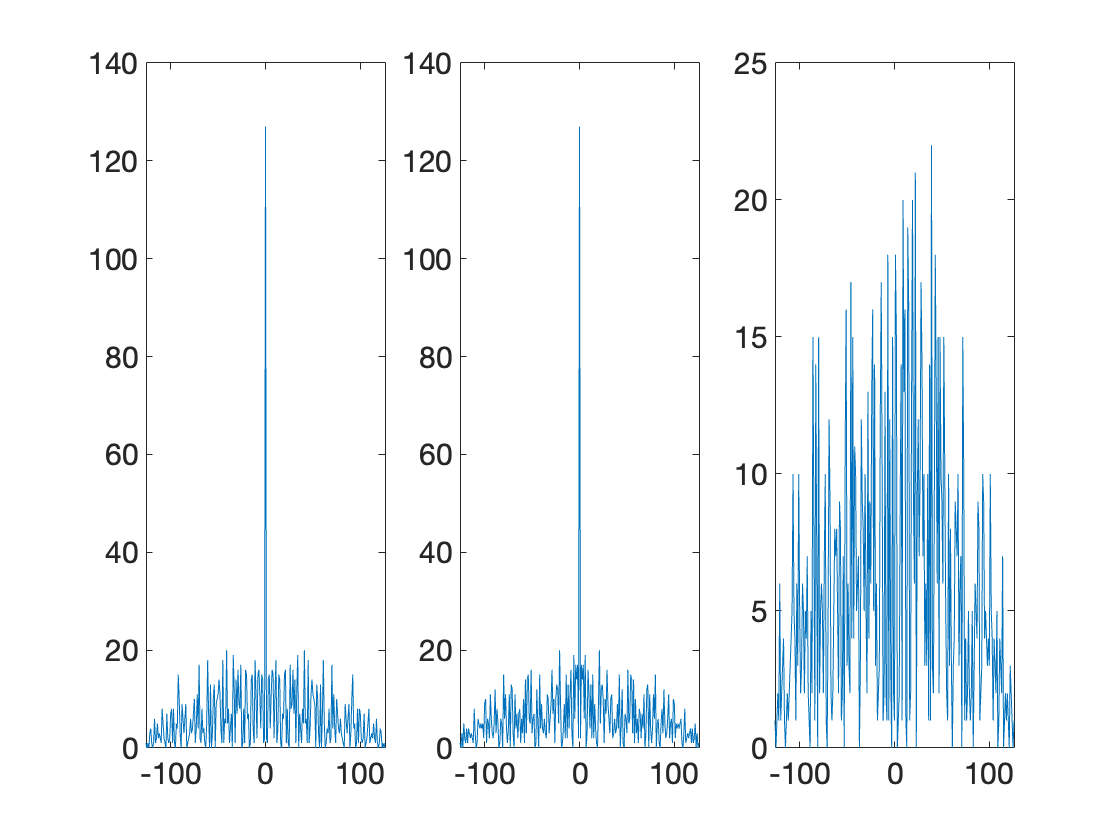

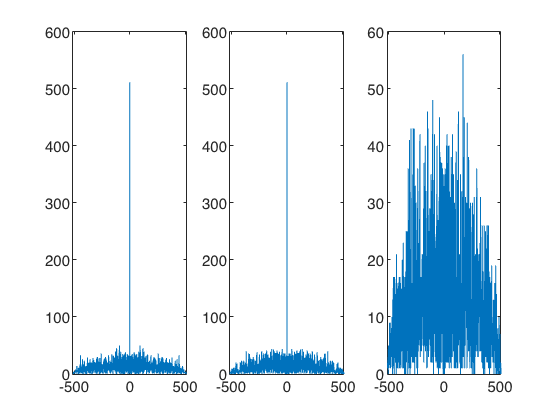

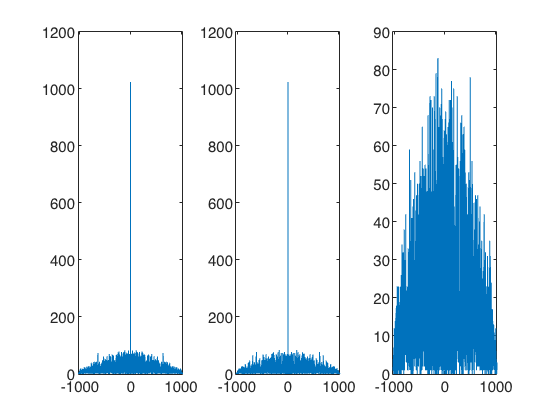

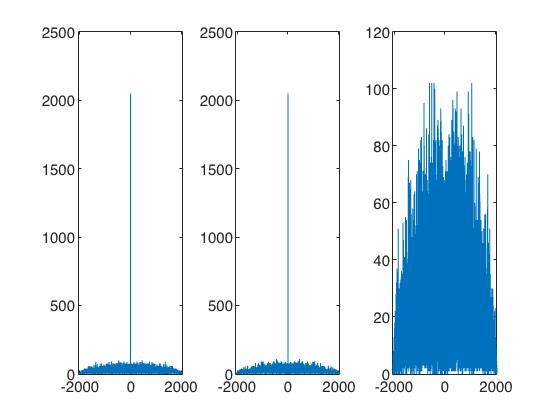

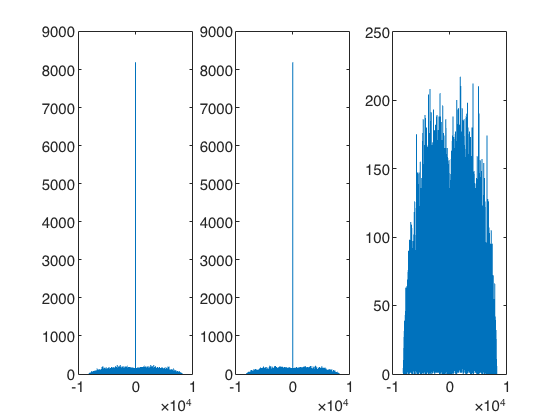



fs = 1e6; % sampling freq
T = 50e-3; % length of the sequence (probe signal) in seconds % (20 - 100ms)
r = 15000; % rate
% filter
rolloff = 1/8;
M = r*T;

N = 500;

% best kasami [14 13 8 4 0]
% best lfsr [10 7 0]
%[23 18 0], [24 23 22 17 0], [25 22 0], [26 25 24 20 0], [27 26 25 22 0], [28 25 0], [29 27 0], [30 29 28 7 0], [31 28 0], [32 31 30 10 0], [33 20 0], [34 15 14 1 0], [35 2 0], [36 11 0], [37 12 10 2 0], [38 6 5 1 0], [39 8 0], [40 5 4 3 0], [41 3 0], [42 23 22 1 0], [43 6 4 3 0], [44 6 5 2 0], [45 4 3 1 0], [46 21 10 1 0], [47 14 0], [48 28 27 1 0], [49 9 0], [50 4 3 2 0], [51 6 3 1 0], [52 3 0], [53 6 2 1 0]
lfsr_polys = {[2 1 0], [4 3 0], [6 5 0], [8 6 5 4 0], [10 7 0], [12 11 8 6 0], [14 13 8 4 0],[16 15 13 4 0], [18 11 0], [19 18 17 14 0], [20 17 0], [21 19 0], [22 21 0]};
kasami_polys = {[4 1 0], [6 1 0], [8 4 3 2 0], [10 3 0], [12 6 4 1 0]};
gold_fpolys = {[5 2 0], [6 1 0], [7 3 0], [9 4 0], [10 3 0], [11 2 0], [13 4 3 1 0]};
gold_spolys = {[5 4 3 2 0], [6 5 2 1 0], [7 3 2 1 0], [9 6 4 3 0], [10 8 3 2 0], [11 8 5 2 0], [13 12 10 9 7 6 5 1 0]};

codeMethod = "gold";
ccnoise_list = {};
psr_list = {};
ccoef_list = {};
acr_list = {};
for i = 1:size(gold_fpolys, 2)
    cinit = 9; 
    anchor1 = genBasebandSig(cinit,M,T,fs,rolloff,codeMethod, cell2mat(gold_fpolys(i)), cell2mat(gold_spolys(i)));
    cinit = 3;      
    anchor2 = genBasebandSig(cinit,M,T,fs,rolloff,codeMethod, cell2mat(gold_fpolys(i)), cell2mat(gold_spolys(i)));

    [cr1,tau1] = xcorr(anchor2,anchor1);
    [ar1,atau1] = xcorr(anchor1,anchor1);
    [ar2,atau2] = xcorr(anchor2,anchor2);
     
    % cross correlation noise
    ccnoise = mean(abs(cr1)); 
    
    % peak to sidelobe ratio
    psr1 = (max(ar1) - mean(ar1)) / std(ar1);
    psr2 = (max(ar2) - mean(ar2)) / std(ar2);

    % autocorrelation peak to cross-correlation ratio
    acr = max(ar1) / mean(cr1);

    % correlation coefficient
    ccoef = abs(corrcoef(anchor2, anchor1));

    figure('DefaultAxesFontSize',18);
    subplot(1,3,1);
    plot(atau1, abs(ar1));
    subplot(1,3,2);
    plot(atau2, abs(ar2));
    subplot(1,3,3);
    plot(tau1, abs(cr1));
    
    ccnoise_list = [ccnoise_list ccnoise];
    psr_list = [psr_list psr1 + psr2 * 0.5];
    ccoef_list = [ccoef_list ccoef(1,2)];
    acr_list = [acr_list acr];
    
end

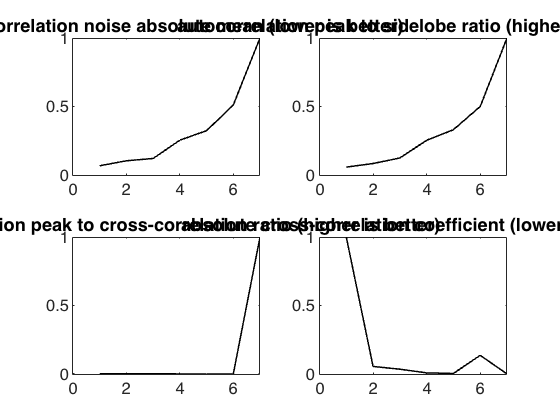

ccnoise_list = cell2mat(ccnoise_list);
ccnoise_list = ccnoise_list / max(ccnoise_list);

psr_list = cell2mat(psr_list);
psr_list = psr_list / max(psr_list);

acr_list = cell2mat(acr_list);
acr_list = acr_list / max(acr_list);

ccoef_list = cell2mat(ccoef_list);
ccoef_list = ccoef_list / max(ccoef_list);

figure('DefaultAxesFontSize',18);
subplot(2,2,1);
plot(ccnoise_list, "k", "LineWidth",1.5); title("cross-correlation noise absolute mean (lower is better)");
subplot(2,2,2);
plot(psr_list, "k", "LineWidth",1.5); title("autocorrelation peak to sidelobe ratio (higher is better)");
subplot(2,2,3);
plot(acr_list, "k", "LineWidth",1.5); title("autocorrelation peak to cross-correlation ratio (higher is better)");
subplot(2,2,4);
plot(ccoef_list, "k", "LineWidth",1.5); title("absolute cross-correlation coefficient (lower is better)");


% n = size(anchor1, 2);
% time = linspace(0, n / fs * 1000, n);
% subplot(2,1,1); plot(time, anchor1 / max(abs(anchor1)), "g", "LineWidth",1.5); title("Anchor 1");
% xlabel("time [ms]"); ylabel("amplitude");
% subplot(2,1,2); plot(time, anchor2 / max(abs(anchor2)), "r", "LineWidth",1.5); title("Anchor 2")
% xlabel("time [ms]"); ylabel("amplitude");
% 
% rx = zeros(1,2*numel(anchor1));
% delay1 = 10e-3; % delay in seconds
% idx = (floor(delay1*fs) + 1):(floor(delay1*fs) + numel(anchor1) );
% rx(idx) = rx(idx) + anchor1;
% delay2 = 20e-3; % delay in seconds
% idx = (floor(delay2*fs) + 1):(floor(delay2*fs) + numel(anchor2));
% rx(idx) = rx(idx) + anchor2;
% 
% [cr1,tau1] = xcorr(anchor2,anchor1);
% [ar1,atau1] = xcorr(anchor1,anchor1);
% [ar2,atau2] = xcorr(anchor2,anchor2);
% subplot(1, 1, 1);
% plot(tau1 / fs * 1000, abs(cr1), "k", "LineWidth",1.5);
% subplot(1, 2, 1);
% plot(atau1 / fs * 1000, abs(ar1) / max(ar1), "k", "LineWidth",1.5);
% subplot(1, 2, 2);
% plot(atau2 / fs * 1000, abs(ar2) / max(ar2), "k", "LineWidth",1.5);
% 
% % correlation quality measures
% 
% % peak to sidelobe ratio
% 
% psr1 = (max(abs(ar1)) - mean(abs(ar1))) / std(abs(ar1))
% psr2 = (max(abs(ar2)) - mean(abs(ar2))) / std(abs(ar2))
% 
% % autocorrelation peak to cross-correlation ratio
% 
% acr1 = max(abs(ar1)) / mean(abs(cr1))